Nombre: Alfredo Robledano Abasolo

Fecha: 03-05-2023

# Ejercicio T7B1

Utiliza la fórmula compuesta de los trapecios para estimar el módulo de rigidez del acero al níquel a partir de los siguientes datos obtenidos en un ensayo.

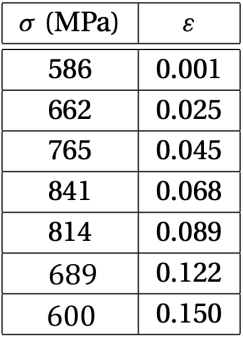

Da el resultado en Mpa redondeado al entero más próximo.

Limpieza del entorno de trabajo:

clc, clear

Datos obtenidos en el ensayo:

s = [586, 662, 765, 841, 814, 689, 600];
e = [0.001, 0.025, 0.045, 0.068, 0.089, 0.122, 0.150];

Se utiliza la fórmula compuesta de los trapecios. Contamos con n+1 puntos y por ello con n subintervalos.

n = numel(s)-1; % nº subintervalos

Se calcula el sumatorio de áreas de trapecios en cada subintervalo:

sum_t = 0;
for i = 1: n
    sum_t = sum_t + (s(i)+s(i+1)) * (e(i+1)-e(i));
end
I = 1/2 * sum_t;

Redondeando obtenemos el resultado deseado

fprintf("El módulo de rigidez toma el valor:\n%d MPa", round(I));

El módulo de rigidez toma el valor:
108 MPa

Podemos dibujar los trapecios utilizados:

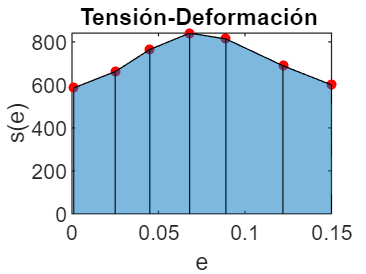

% Límites del dibujo
l1_e = 0; l2_e = max(e);
l1_s = 0; l2_s = max(s);
% Dibujamos los puntos dato
plot(e, s, 'r.', MarkerSize=12)
hold on
% Utilizamos los límites definidos
xlim([l1_e, l2_e]); ylim([l1_s, l2_s]);
% Dibujamos los trapecios definidos por líneas negras
% y sus áreas en azul
for i=1:n
    plot([e(i), e(i+1)], [s(i), s(i+1)], 'k-')
    plot([e(i), e(i)], [s(i), 0], 'k-')
    area([e(i), e(i+1)], [s(i), s(i+1)], FaceColor="#0072BD", FaceAlpha=0.5)
end
plot([e(i+1), e(i+1)], [s(i+1), 0], 'k-')
% Etiquetas
title('Tensión-Deformación ')
xlabel('e'); ylabel('s(e)')
hold off

for i = 1:1
    disp('hi')
end

hi
